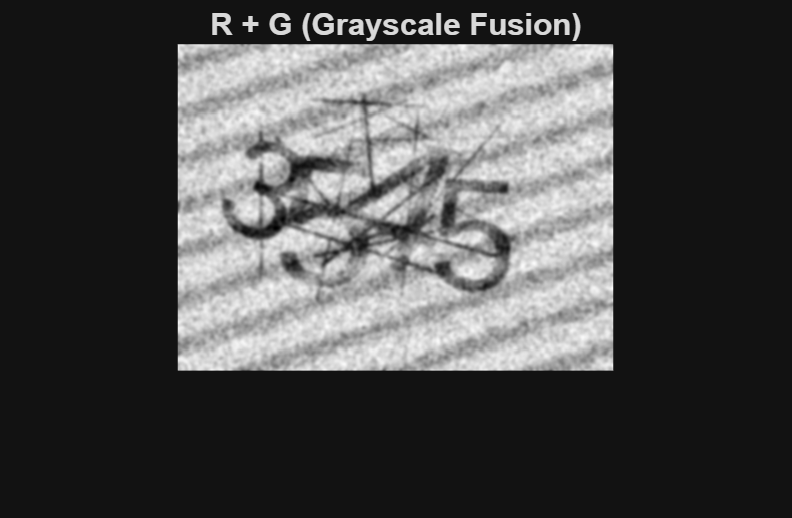

I = imread("C:\UPPSALA 2025\INTRODUCTION TO IMAGE ANALYSIS\Intro2IA_Mini_Project_complete\Train\captcha_0002.png");
% Ig = im2double(rgb2gray(I));
% 
% figure; imshow(Ig,[]); title("Original grayscale");
% Read original RGB image

% Split into RGB channels
R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);

RG_gray = mat2gray(0.5*double(R) + 0.5*double(G));

figure;
imshow(RG_gray, []);
title('R + G (Grayscale Fusion)');

% % Display
% figure;
% subplot(2,2,1), imshow(I), title('Original Image');
% subplot(2,2,2), imshow(R, []), title('Red Channel');
% subplot(2,2,3), imshow(G, []), title('Green Channel');
% subplot(2,2,4), imshow(B, []), title('Blue Channel');




% F = fft2(Ig);
% Fshift = fftshift(F);
% 
% spec = log(1 + abs(Fshift));
% 
% figure; imshow(mat2gray(spec),[]); title("FFT log-magnitude spectrum");


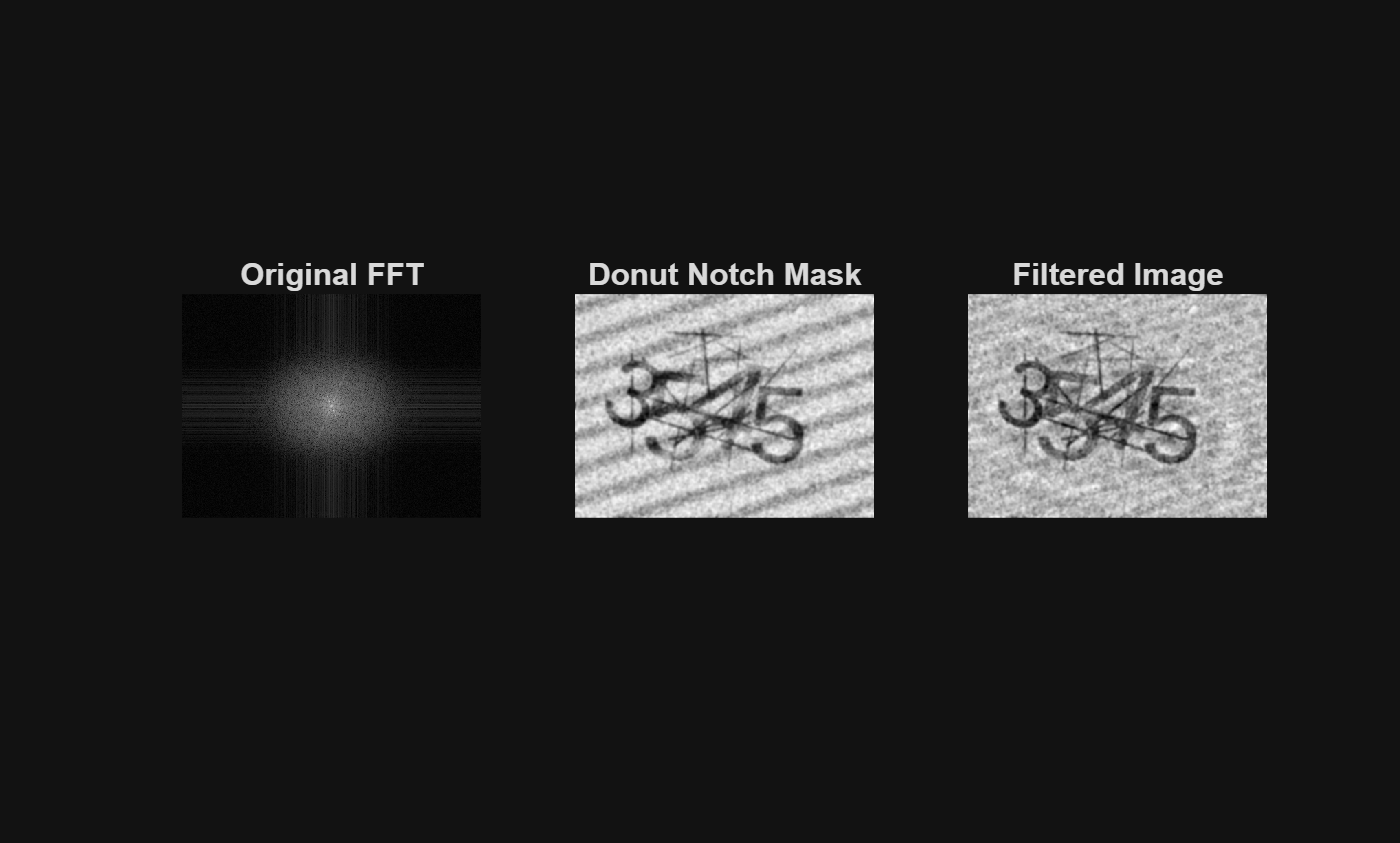

% -----------------------------
% DONUT (RING) NOTCH FILTER
% -----------------------------

% Compute FFT
F = fft2(RG_gray);
Fshift = fftshift(F);

[h, w] = size(Fshift);
[cx, cy] = deal(floor(w/2)+1, floor(h/2)+1);

% ------------ Notch ring parameters ------------
inner_r = 6;   % block this radius and outward
outer_r = 9;  % stop blocking after this radius
% Set these to what you need

% ------------ Create donut-shaped mask ------------
[x, y] = meshgrid(1:w, 1:h);
dist = sqrt((x - cx).^2 + (y - cy).^2);

% 1 = keep, 0 = notch
donut_mask = ~(dist >= inner_r & dist <= outer_r);

% ------------ Apply notch ring ------------
F_notched = Fshift .* donut_mask;

% ------------ Inverse FFT ------------
F_notched = ifftshift(F_notched);
Ig_clean = real(ifft2(F_notched));

% ------------ Show results ------------
figure;
subplot(1,3,1); imshow(log(1+abs(Fshift)), []); title('Original FFT');
subplot(1,3,2); imshow(RG_gray, []); title('Donut Notch Mask');
subplot(1,3,3); imshow(Ig_clean, []); title('Filtered Image');

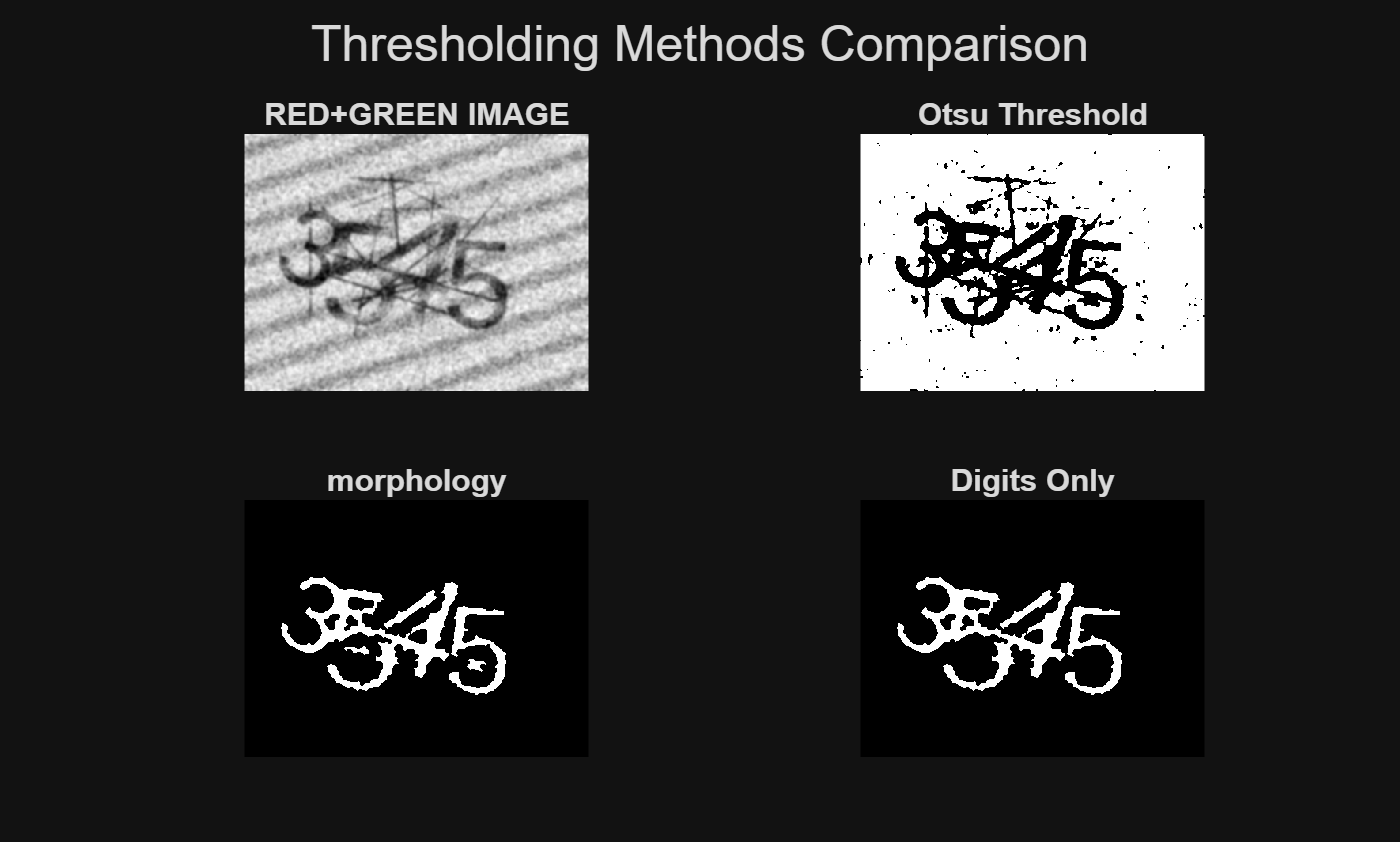

% -------------------------------------------------------
% INPUT: FFT-filtered image after combining 2 channels
% -------------------------------------------------------
I = mat2gray(Ig_clean);   % <-- replace with your variable

figure;

subplot(2,2,1)
imshow(RG_gray), title('RED+GREEN IMAGE')

% -------------------------------------------------------
% 2. Otsu Threshold
% -------------------------------------------------------
T_otsu = graythresh(I);
BW_otsu = imbinarize(I, T_otsu);

subplot(2,2,2)
imshow(BW_otsu), title('Otsu Threshold')



% BW = ~imbinarize(I2);
BW_otsu = ~BW_otsu;


BW_otsu = imerode(BW_otsu, strel('disk', 4));
BW_otsu = bwareaopen(BW_otsu, 100 );
BW_otsu = imdilate(BW_otsu, strel('disk', 1));

subplot(2,2,3)
imshow(BW_otsu), title('morphology')

% BW_otsu = medfilt2(BW_otsu, [3 3]); 


% ---------- Connected components on Otsu result ----------

% 1. Connected components (8-connectivity)
cc = bwconncomp(BW_otsu, 8);

% 2. Measure components
stats = regionprops(cc, 'Area', 'BoundingBox', 'Centroid');

% 3. Filter components by area (keep digits, remove noise)
areas = [stats.Area];
minArea = 260;
maxArea = numel(BW_otsu) * 0.06;

validIdx = find(areas > minArea & areas < maxArea);

% 4. Build clean digit mask
BW_digits = false(size(BW_otsu));
for k = validIdx
    BW_digits(cc.PixelIdxList{k}) = true;
end

subplot(2,2,4), imshow(BW_digits), title('Digits Only');

sgtitle('Thresholding Methods Comparison')

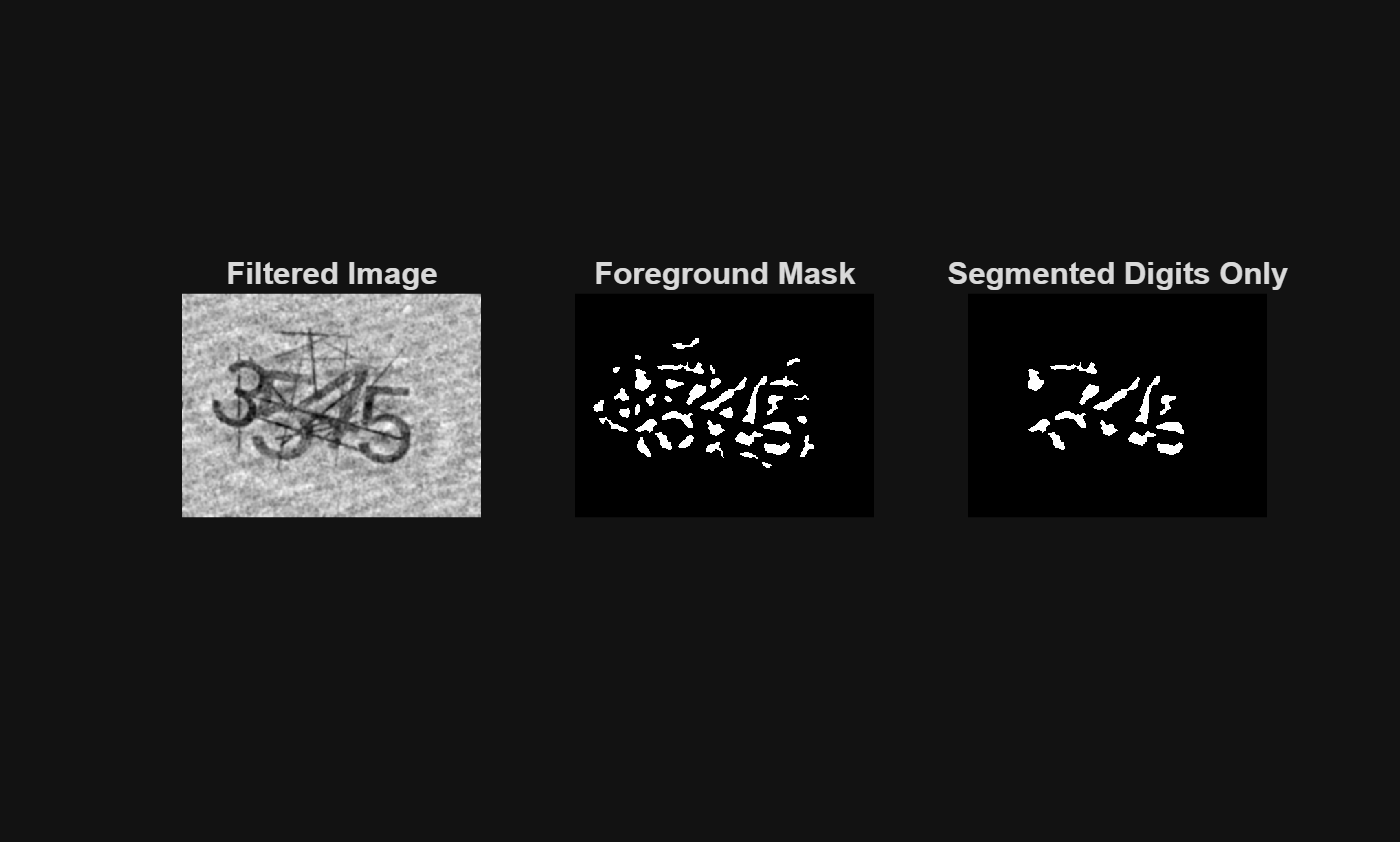

% ---------------------------------------------------------------
% STEP 1 — Input: filtered image after your donut-notch FFT step
% ---------------------------------------------------------------
I = Ig_clean;              % Your filtered grayscale image
I = mat2gray(I);

% ---------------------------------------------------------------
% STEP 2 — Smooth heavily to remove speckle noise
% ---------------------------------------------------------------
I_smooth = imgaussfilt(I, 2);       % sigma=2 works well; increase if noisier

% ---------------------------------------------------------------
% STEP 3 — Adaptive thresholding for foreground extraction
% ---------------------------------------------------------------
T = adaptthresh(I_smooth, 0.40);    % sensitivity 0.45 → good for noisy scans
BW = imbinarize(I_smooth, T);
% 
% % Invert if needed (digits should be white)
% if mean(I(BW)) < mean(I(~BW))
%     BW = ~BW;
% end

% ---------------------------------------------------------------
% STEP 4 — Morphological cleanup
% ---------------------------------------------------------------
BW = bwareaopen(BW, 50);            % remove tiny dots
BW = imclose(BW, strel('disk', 4)); % close gaps in digits
BW = imfill(BW, 'holes');           % fill holes in digits

% ---------------------------------------------------------------
% STEP 5 — Extract digits (connected components)
% ---------------------------------------------------------------
CC = bwconncomp(BW);
stats = regionprops(CC, 'BoundingBox', 'Area');

% Keep only reasonably large blobs (foreground digits)
minArea = 300;
idx = find([stats.Area] > minArea);

% Mask with only digits
BW_digits = false(size(BW));
for k = idx
    BW_digits(CC.PixelIdxList{k}) = true;
end

% ---------------------------------------------------------------
% SHOW RESULTS
% ---------------------------------------------------------------
figure;
subplot(1,3,1), imshow(I, []), title('Filtered Image');
subplot(1,3,2), imshow(BW, []), title('Foreground Mask');
subplot(1,3,3), imshow(BW_digits, []), title('Segmented Digits Only');

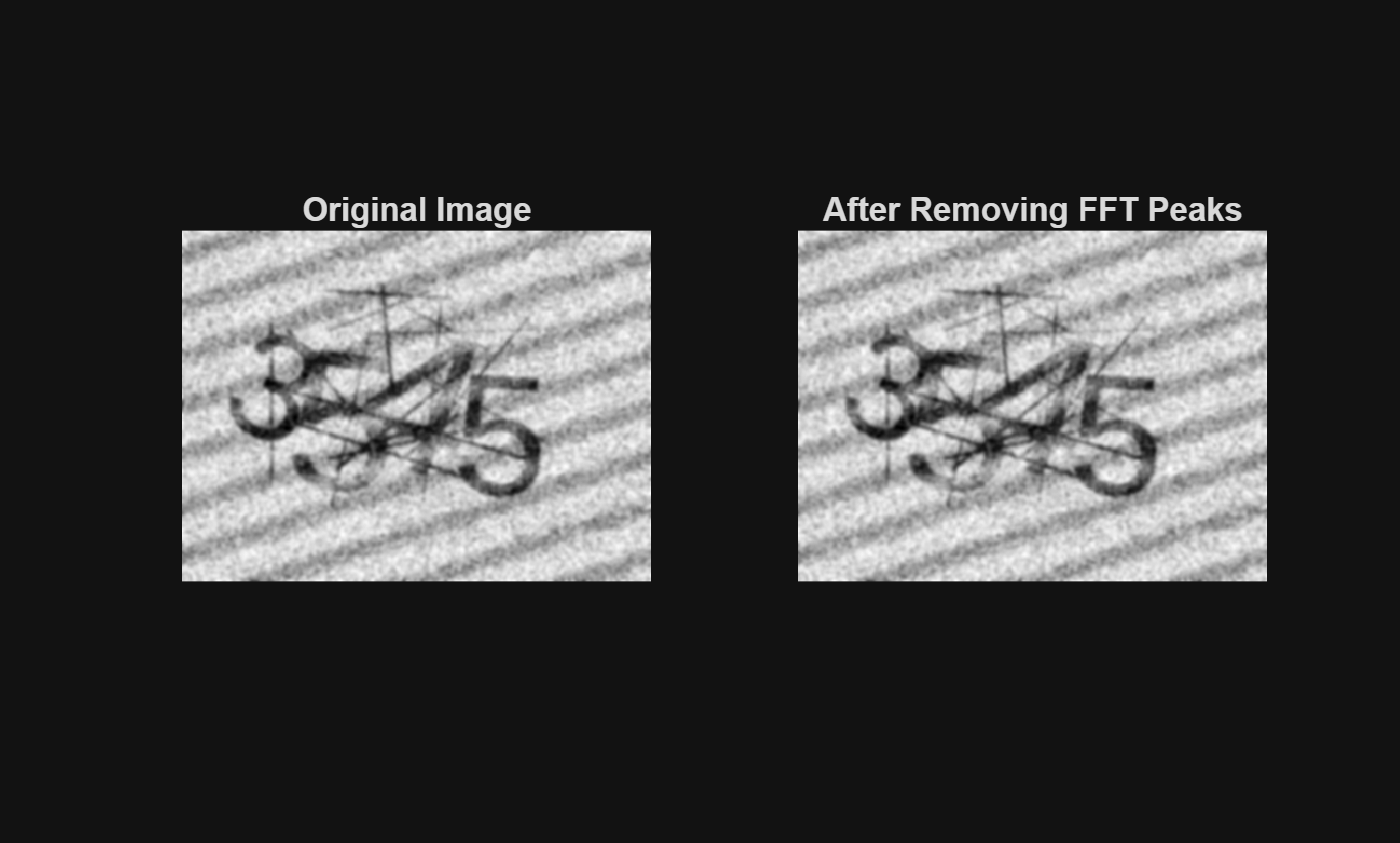

% ---------- Automatic detection & removal of side FFT peaks ----------

% Compute FFT
F = fft2(Ig);
Fshift = fftshift(F);
spec = log(1 + abs(Fshift));

[h, w] = size(spec);
cx = floor(w/2) + 1;
cy = floor(h/2) + 1;

% ---------- 1. Detect the two bright symmetric peaks ----------
% Take horizontal slice through the center
row = spec(cy, :);

% Mask out the bright DC region (±20 px around center)
mask = true(1, w);
mask(cx-20:cx+20) = false;
row2 = row .* mask;

% Get locations of the two strongest peaks
[~, idxs] = maxk(row2, 2);
xp = sort(idxs).';     % x positions of the peaks
yp = [cy; cy];         % both peaks lie on same center row

% ---------- 2. Remove the peaks (notch filtering) ----------
notch_radius = 3;
F_clean = Fshift;

for k = 1:2
    x = xp(k); 
    y = yp(k);

    % Zero-out neighborhood around the detected peak
    F_clean(y-notch_radius:y+notch_radius, ...
            x-notch_radius:x+notch_radius) = 0;

    % Zero-out symmetric peak on opposite side
    xs = 2*cx - x;
    ys = 2*cy - y;

    F_clean(ys-notch_radius:ys+notch_radius, ...
            xs-notch_radius:xs+notch_radius) = 0;
end

% ---------- 3. Inverse FFT ----------
F_clean = ifftshift(F_clean);
Ig_clean = real(ifft2(F_clean));

% ---------- 4. Display result ----------
figure; 
subplot(1,2,1); imshow(Ig, []); title('Original Image');
subplot(1,2,2); imshow(Ig_clean, []); title('After Removing FFT Peaks');

[M,N] = size(Ig);
[X,Y] = meshgrid(1:N,1:M);

% parameters to tune
sigma = 5;          % width of notch
strength = 0.1;    % 0 -> kill completely, 1 -> no filtering

filter_mask = ones(M,N);

for k = 1:length(xp)
    cx = xp(k); 
    cy = yp(k);

    % Gaussian notch
    G = exp(-((X-cx).^2 + (Y-cy).^2)/(2*sigma^2));
    G = 1 - (1-strength) * G;

    % symmetric peak
    cx2 = N - cx + 1;
    cy2 = M - cy + 1;

    G2 = exp(-((X-cx2).^2 + (Y-cy2).^2)/(2*sigma^2));
    G2 = 1 - (1-strength) * G2;

    filter_mask = filter_mask .* G .* G2;
end


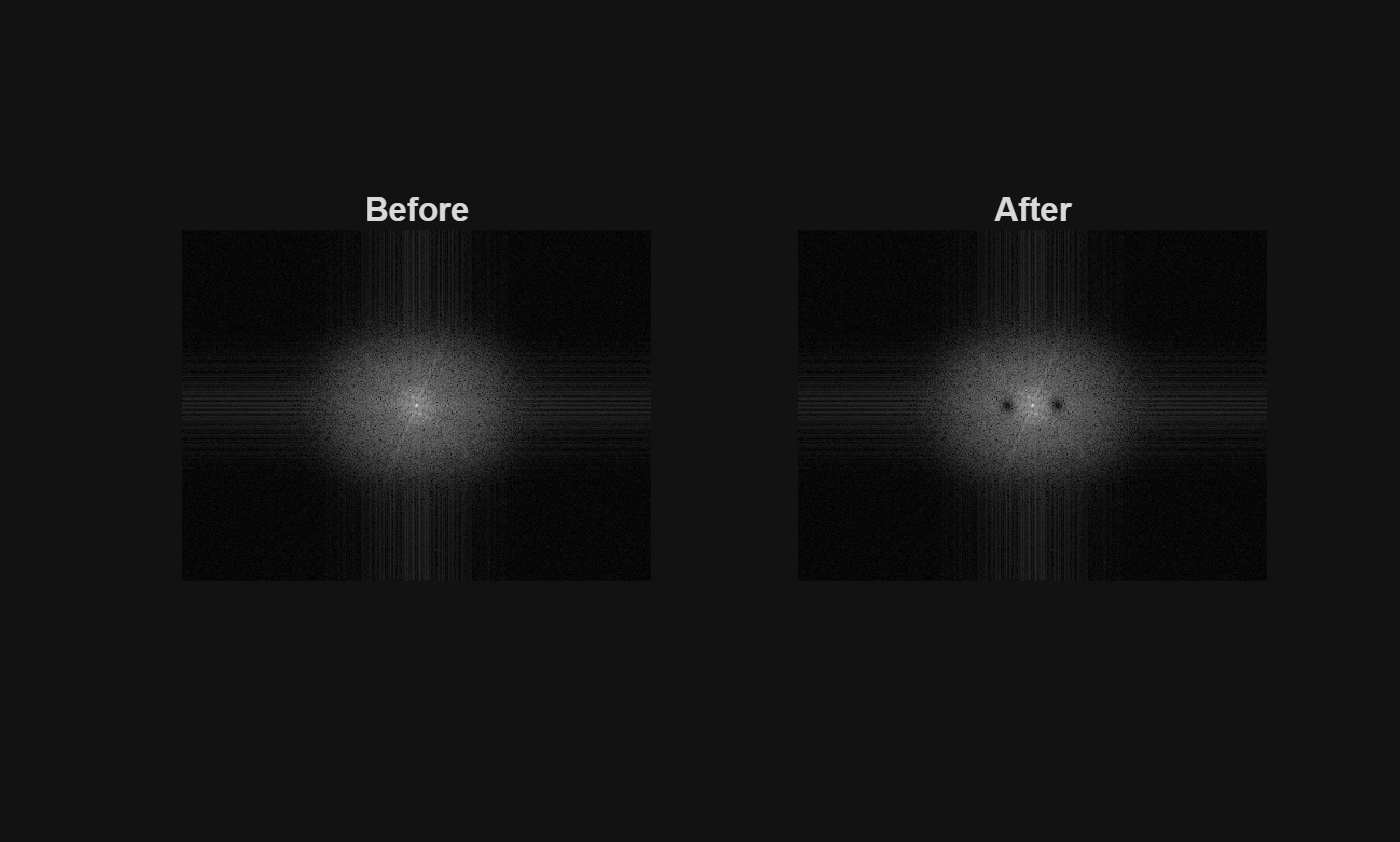

Ff = Fshift .* filter_mask;

spec_after = log(1 + abs(Ff));

figure; 
subplot(1,2,1); imshow(mat2gray(spec),[]); title("Before");
subplot(1,2,2); imshow(mat2gray(spec_after),[]); title("After");

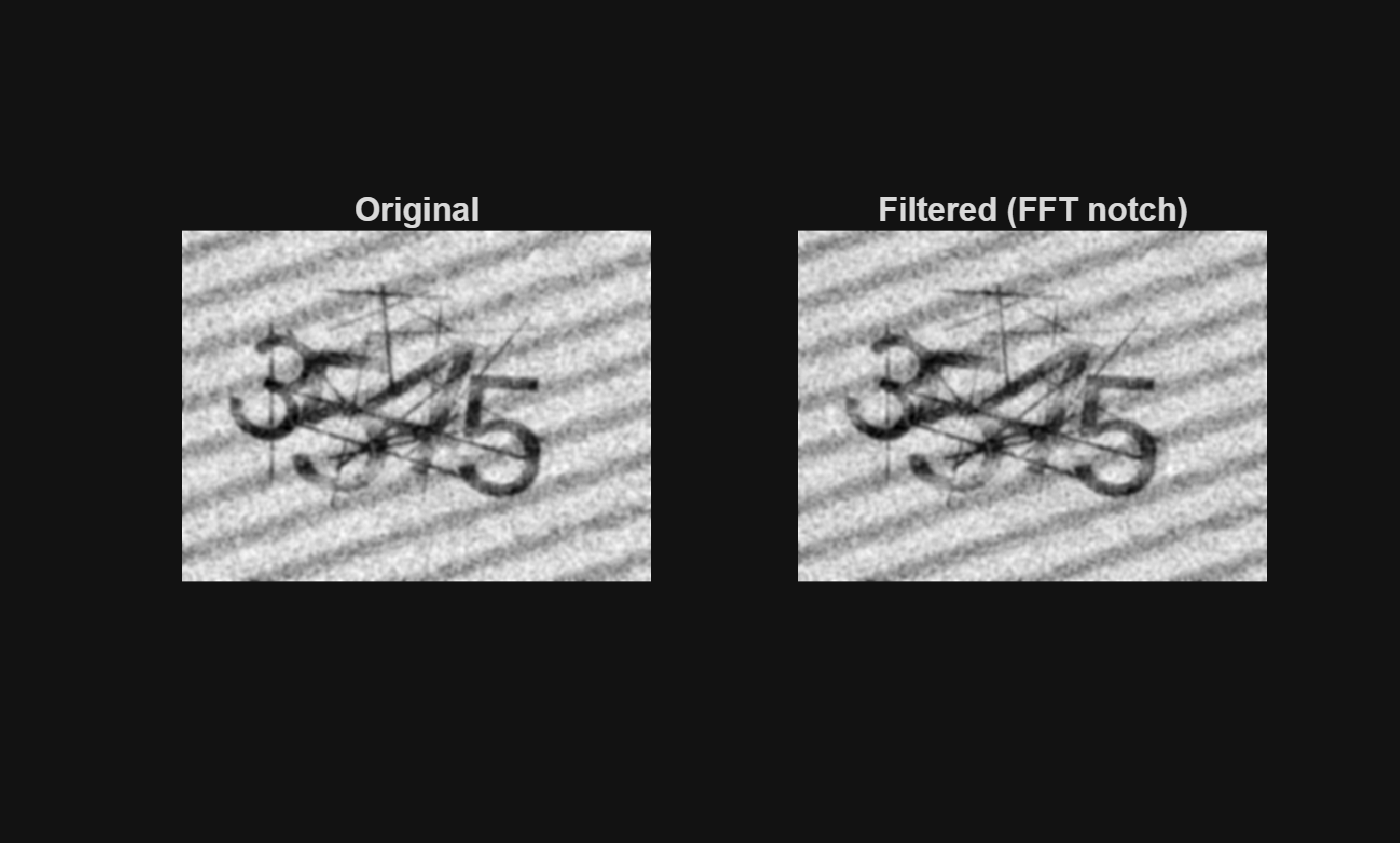

If = ifft2(ifftshift(Ff));
If = real(If);
If = mat2gray(If);

figure; 
subplot(1,2,1); imshow(Ig,[]); title("Original");
subplot(1,2,2); imshow(If,[]); title("Filtered (FFT notch)");

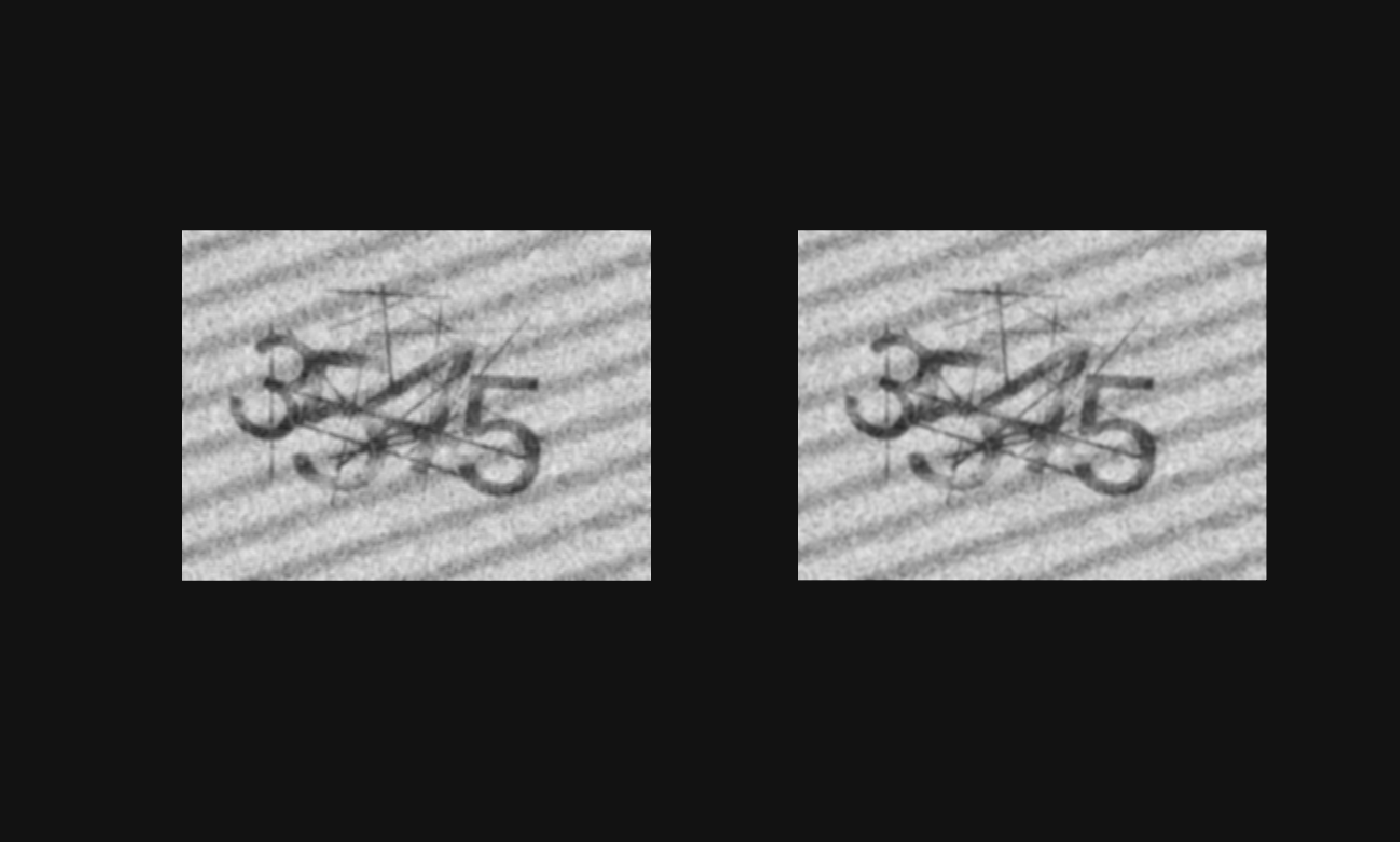

denoised = wdenoise(Ig_clean , 3, 'Wavelet', 'db2', 'DenoisingMethod', 'Bayes');
denoisedl2 = medfilt2(Ig_clean, [2 2]);   % try [5 5] for stronger effect
% denoisedl3 = imgaussfilt(denoisedl2, 1.2);
figure;
subplot(1, 2, 1);
imshow(denoised);
subplot(1, 2, 2);
imshow(denoisedl2);

% subplot(1, 3, 3);
% imshow(denoisedl3);


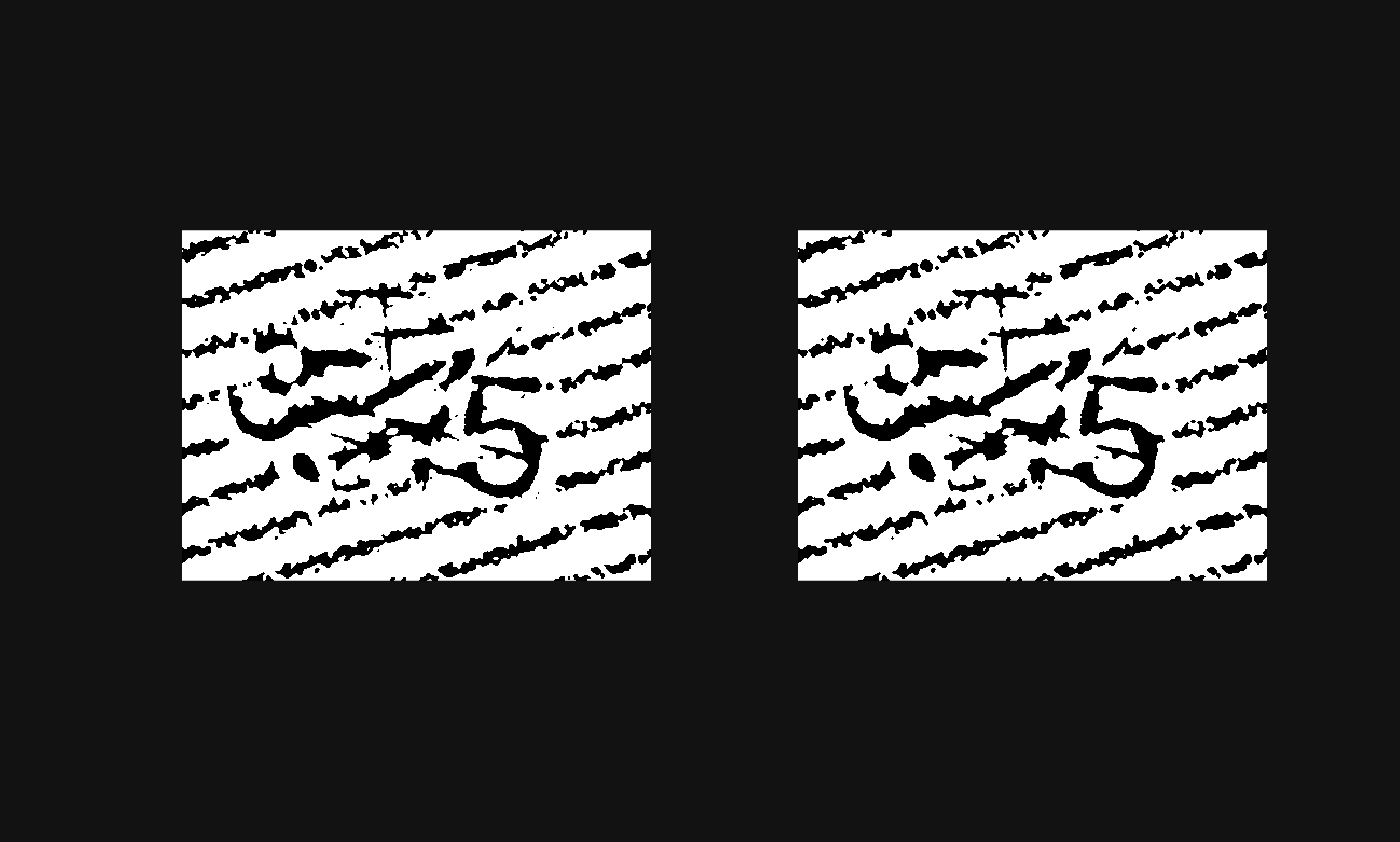

mask = imbinarize(J, 'adaptive', 'ForegroundPolarity','dark', 'Sensitivity',0.50);   % adjust 0.40–0.70
figure;
subplot(1,2, 1)
imshow(mask);
% mask = bwareaopen(mask, 1);             % remove small dots
mask = imclose(mask, strel('disk',1));  % connect broken strokes
mask = imerode(mask, strel('arbitrary', 10));
% mask = imfill(mask,'holes');             % fill digit interiors
subplot(1,2, 2)
imshow(mask);

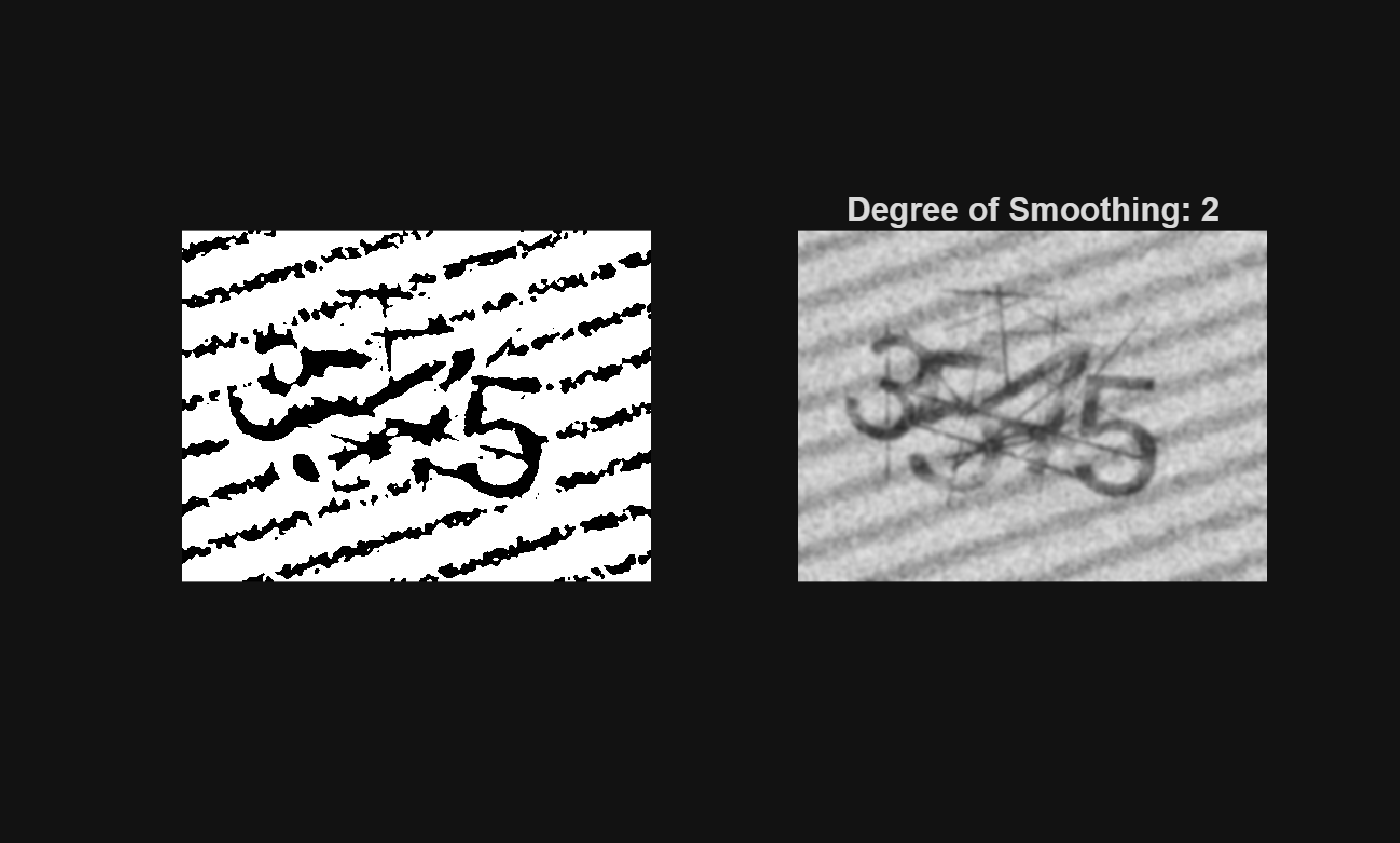

patch = imcrop(Ig_clean,[170, 35, 50 50]);
% imshow(patch);
patchVar = 1;
DoS = 2*patchVar;
J = imbilatfilt(Ig_clean,DoS);
imshow(J);
title(['Degree of Smoothing: ',num2str(DoS)])

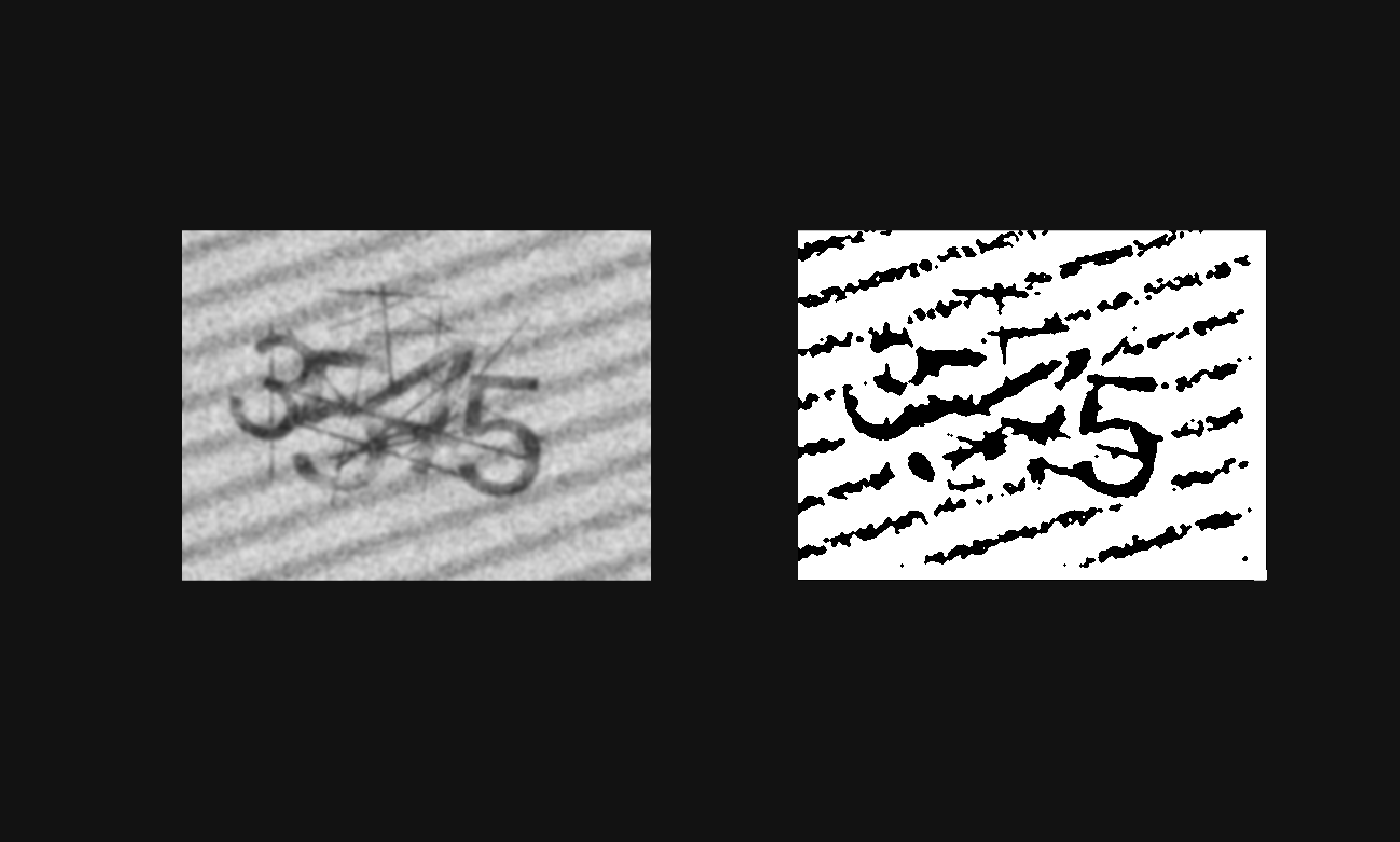

denoisedl2 = medfilt2(J, [2 2]);   % try [5 5] for stronger effect


mask = imbinarize(denoisedl2, 'adaptive', 'ForegroundPolarity','dark', 'Sensitivity',0.50);   % adjust 0.40–0.70
figure;
subplot(1,2, 1)
imshow(J);
% mask = bwareaopen(mask, 1);             % remove small dots
mask = imclose(mask, strel('disk',1));  % connect broken strokes
mask = imerode(mask, strel('arbitrary', 10));
% mask = imfill(mask,'holes');             % fill digit interiors
subplot(1,2, 2)
imshow(mask);